
N_br = 5;
N = 64;
M = 71;
F_s = 2000;
T_s = 1/F_s;
A1 = 1.05;
A2 = 2.1;
f1 = 500;
f2 = 750;

## Задание 1

disp("Задание 1")

Задание 1


n_1_N = 0:1:N-1;
n_1_M = 0:1:M-1;
x_1 = A1*cos(2*pi*f1*T_s*n_1_N) + A2*cos(2*pi*f2*T_s*n_1_N);
x_1_2 = A1*cos(2*pi*f1*T_s*n_1_M) + A2*cos(2*pi*f2*T_s*n_1_M);
%% вычисление спектра
X_1 = abs(fft(x_1));
X_1_2 = abs(fft(x_1_2));
fprintf('M = 71, x(n)^2: %f, |X(f)|^2: %f', sum(x_1_2.^2), sum(X_1_2.*X_1_2)/M);

M = 71, x(n)^2: 196.245000, |X(f)|^2: 196.245000

fprintf('N = 64, x(n)^2: %f, |X(f)|^2: %f', sum(x_1.^2), sum(X_1.*X_1)/N);

N = 64, x(n)^2: 176.400000, |X(f)|^2: 176.400000

## Задание 2

disp("Задание 2")

Задание 2


Растекание присутсвует


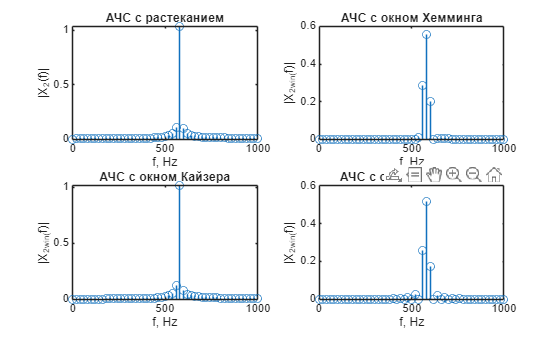

N_2 = 100;
f1_2 = 578;
n_2_N = 0:1:N_2-1;
x_2 = A1*cos(2*pi*f1_2*T_s*n_2_N);
%% проверим на растекание
P_2 = (F_s/N_2)*n_2_N;
flag = 0; % флаг на растекание
for i = 1:length(P_2)
    if P_2(i)==f1_2
        flag = 0;
        break
    else 
        flag = 1;
    end
end

if flag == 1
    disp("Растекание присутсвует")
    win_N_hamming = hamming(N_2)';
    win_N_kaiser = kaiser(N_2)';
    win_N_bartlett = bartlett(N_2)';
    
subplot(2,2,1)
    X_2 = fft(x_2);
    MOD_X_2 = 2/N_2*abs(X_2);
    MOD_X_2(1) = 1/N_2*abs(X_2(1));
    stem((0:N_2-1)*F_s/N_2, MOD_X_2), xlim([0 F_s/2]), title("АЧС с растеканием"), xlabel("f, Hz"), ylabel("|X_2(f)|");
   % plot(0:N_2-1, win_N), title("Окно Хемминга");
subplot(2,2,2)
    X_2_2 = fft(x_2.*win_N_hamming);
    MOD_X_2_2 = 2/N_2*abs(X_2_2);
    MOD_X_2_2(1) = 1/N_2*abs(X_2_2(1));
    stem((0:N_2-1)*F_s/N_2, MOD_X_2_2), xlim([0 F_s/2]), title("АЧС с окном Хемминга"), xlabel("f, Hz"), ylabel("|X_2_w_i_n_(f)|");
subplot(2,2,3)
    X_2_3 = fft(x_2.*win_N_kaiser);
    MOD_X_2_3 = 2/N_2*abs(X_2_3);
    MOD_X_2_3(1) = 1/N_2*abs(X_2_3(1));
    stem((0:N_2-1)*F_s/N_2, MOD_X_2_3), xlim([0 F_s/2]), title("АЧС с окном Кайзера"), xlabel("f, Hz"), ylabel("|X_2_w_i_n_(f)|")
subplot(2,2,4)
    X_2_4 = fft(x_2.*win_N_bartlett);
    MOD_X_2_4 = 2/N_2*abs(X_2_4);
    MOD_X_2_4(1) = 1/N_2*abs(X_2_4(1));
    stem((0:N_2-1)*F_s/N_2, MOD_X_2_4), xlim([0 F_s/2]), title("АЧС с окном Бартлетта"), xlabel("f, Hz"), ylabel("|X_2_w_i_n_(f)|");
else
    disp("Растекания нет. Расходимся")
end 

## Задание 3

disp("Задание 3")

Задание 3


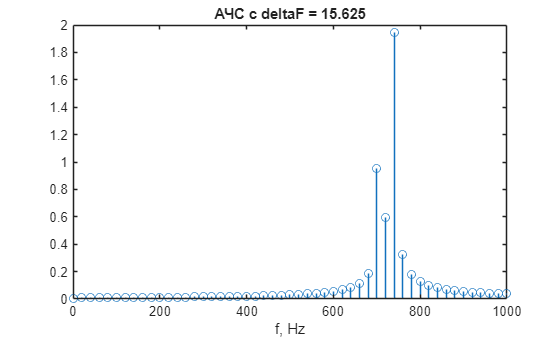

f1 = 500;
n_3 = 0:1:2*N-1;
f11 = 1.1*f1;
f22 = 1.15*f1;
delta_f = F_s/(2*N);
x_3 = A1*cos(2*pi*f11*T_s*n_3) + A2*cos(2*pi*f22*T_s*n_3);
X_3 = fft(x_3);
MOD_3 = abs(X_3)*(2/(2*N));
MOD_3(1) = (1/(2*N))*abs(X_3(1));
flag = 0;
%%% проверка выполнения условния различимости близких гармоник. 
if (abs(f11-f22) > delta_f) && (abs(f11-f22) < 2*delta_f)
    L = ceil(F_s/(abs(f11-f22) - delta_f));
    X_3_2 = fft(x_3, L);
    MOD_3_2 = abs(X_3_2)*(2/(2*N));
    MOD_3_2(1) = (1/(2*N))*abs(X_3_2(1));
    flag = 1;
else
    disp("что-то пошло нитак")
end

figure;
stem((0:2*N-1)*F_s/N_2, MOD_3), title(strcat(['АЧС c deltaF = ' num2str(delta_f)])), xlabel('f, Hz'), xlim([0 F_s/2]);

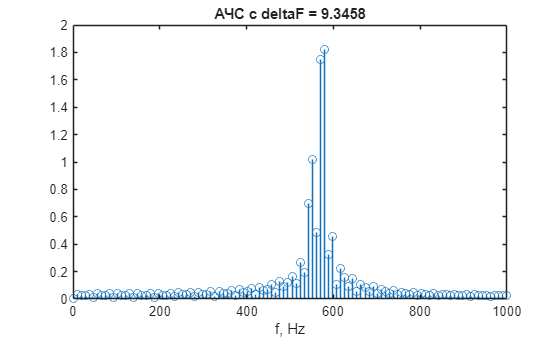

if flag == 1
    stem((0:L-1)*F_s/L, MOD_3_2), title(strcat(['АЧС c deltaF = ' num2str(F_s/length(MOD_3_2))])), xlabel('f, Hz'), xlim([0 F_s/2]);
end

## Задание 4

disp("Задание 4")

Задание 4


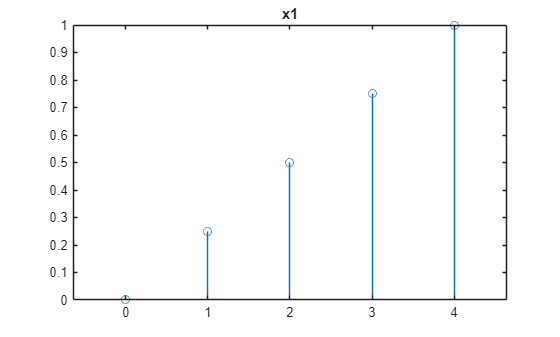

x_4_1 =[0 0.25 0.50 0.75 1];
x_4_2 = [1 0.5 0 0.5 1];
L = length(x_4_1) + length(x_4_2) - 1;
X_4_1 = fft(x_4_1, L);
X_4_2 = fft(x_4_2, L);
Y = ifft(fft(x_4_1).*fft(x_4_2));
figure;
stem(0:length(x_4_1)-1, x_4_1), title('x1');

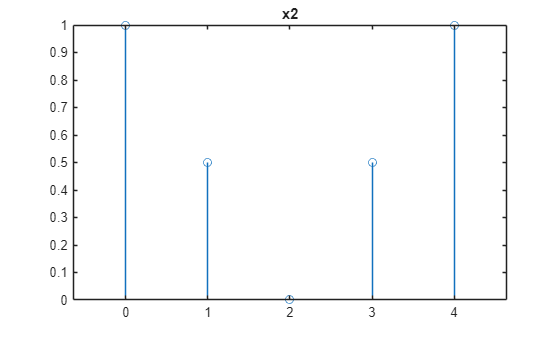

stem(0:length(x_4_2)-1, x_4_2), title('x2');

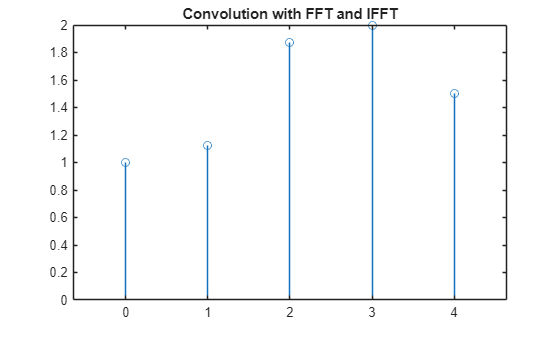

stem(0:length(Y)-1, Y), title('Convolution with FFT and IFFT')

## Задание 5

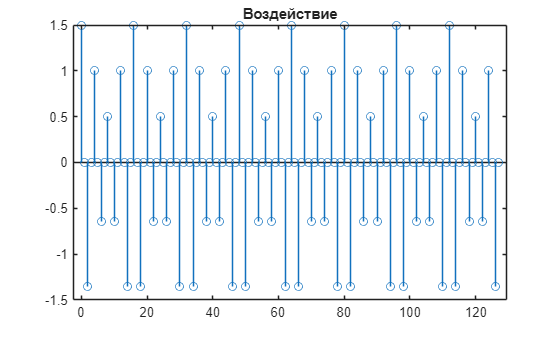

C = 1;
w0 = 2*pi/4;
fi_0 = 0;
Omg = w0/4;
fi_Omg = 0;
m = 0.5;
b = [0.6 0.64272 0.6];
a = [1 0.9028 0.67];
N1 = 25;
n_5 = 0:1:2*N-1;
x_5 = C*(1 + m*cos(Omg*n_5 + fi_Omg)).*cos(w0*n_5 + fi_0);
figure;
stem(n_5, x_5), title('Воздействие');

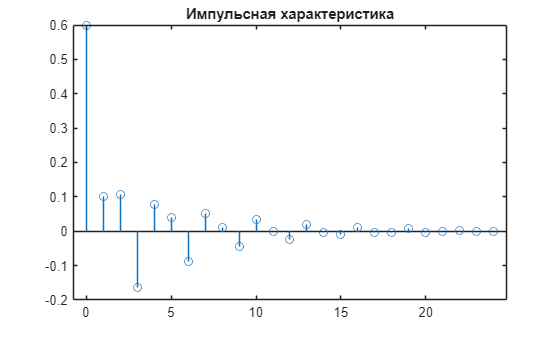

h_5 = impz(b,a,N1);
stem(0:N1-1, h_5), title('Импульсная характеристика');

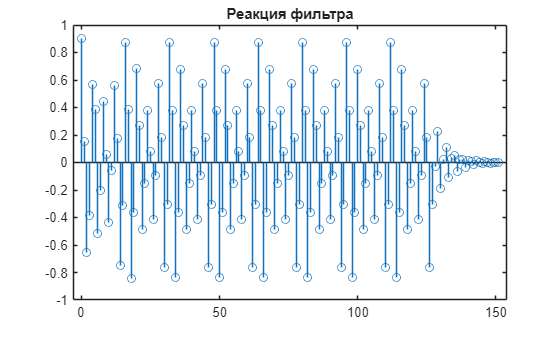

N_lin_conv = length(h_5) + length(x_5) - 1
y_5 = ifft(fft(h_5', N_lin_conv).*fft(x_5, N_lin_conv));
stem(0:length(y_5)-1, y_5), title('Реакция фильтра');

## Задание 6

disp('Задание 6')

Задание 6


N_6 = 4*N;
n_6 = 0:1:N_6-1;
x_6 = C*(1 + m*cos(Omg*n_6 + fi_Omg)).*cos(w0*n_6 + fi_0);
h_6 = impz(b,a,N1)';
y_6 = fftfilt(h_6,x_6,N_6+N1-1);
stem(0:N1-1, h_6), title('Импульсная характеристика')

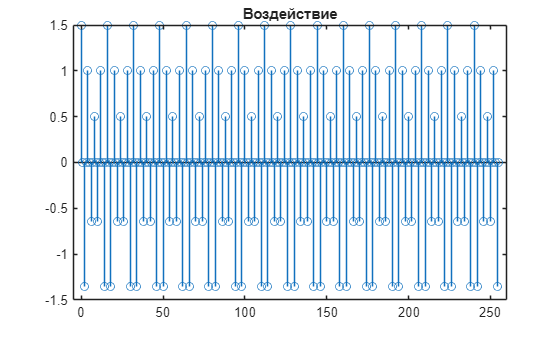

stem(n_6, x_6), title('Воздействие'); 

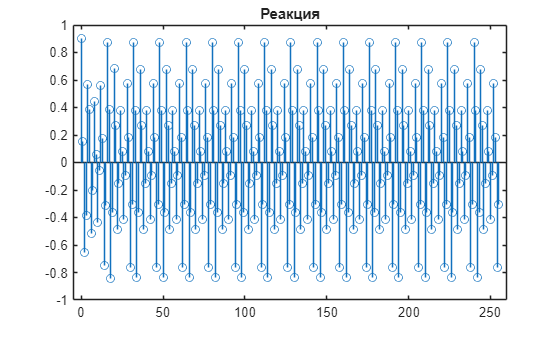

stem(n_6, y_6), title('Реакция');